#### With and Without LQR

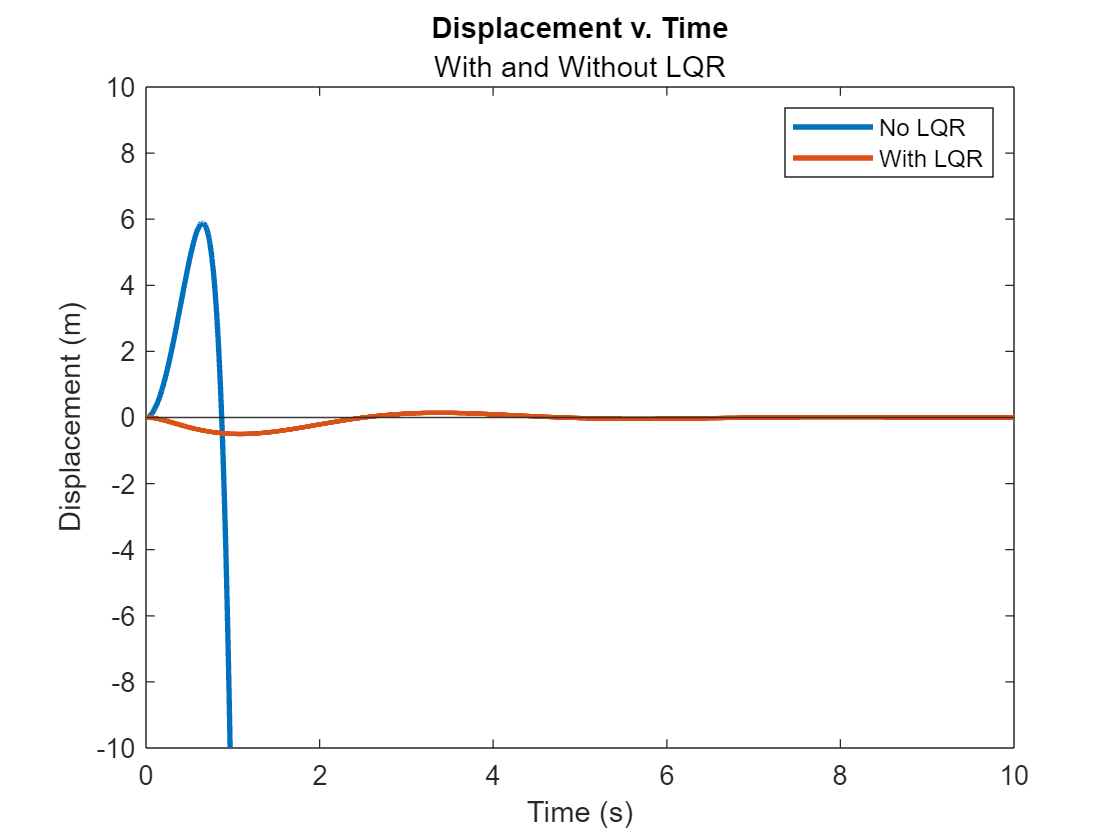

time_t = [0:0.001:20];
IP = InvertedPendulum("b",0.5);
V0 = [0;0; 0.175;0]; % initial bar tilt 10 degrees
%V0 = [0;0; 0;0];

Q = [1 0 0 0;
     0 0 0 0;
     0 0 1 0;
     0 0 0 0];
R=1;
N = [1;0;0;0];
Force =30;
sr = IP.euler_method(V0, Force, time=time_t, lqr=false, ...
    Q=Q,N=N,R=R, description='No LQR');

sr.plotX;

sr2 = IP.euler_method(V0, Force, time=time_t, lqr=true, ...
    Q=Q,N=N,R=R, description='With LQR');
hold on
sr2.plotX
hold off
xlim([0 10])
ylim([-10 10])
legend()
subtitle('With and Without LQR')

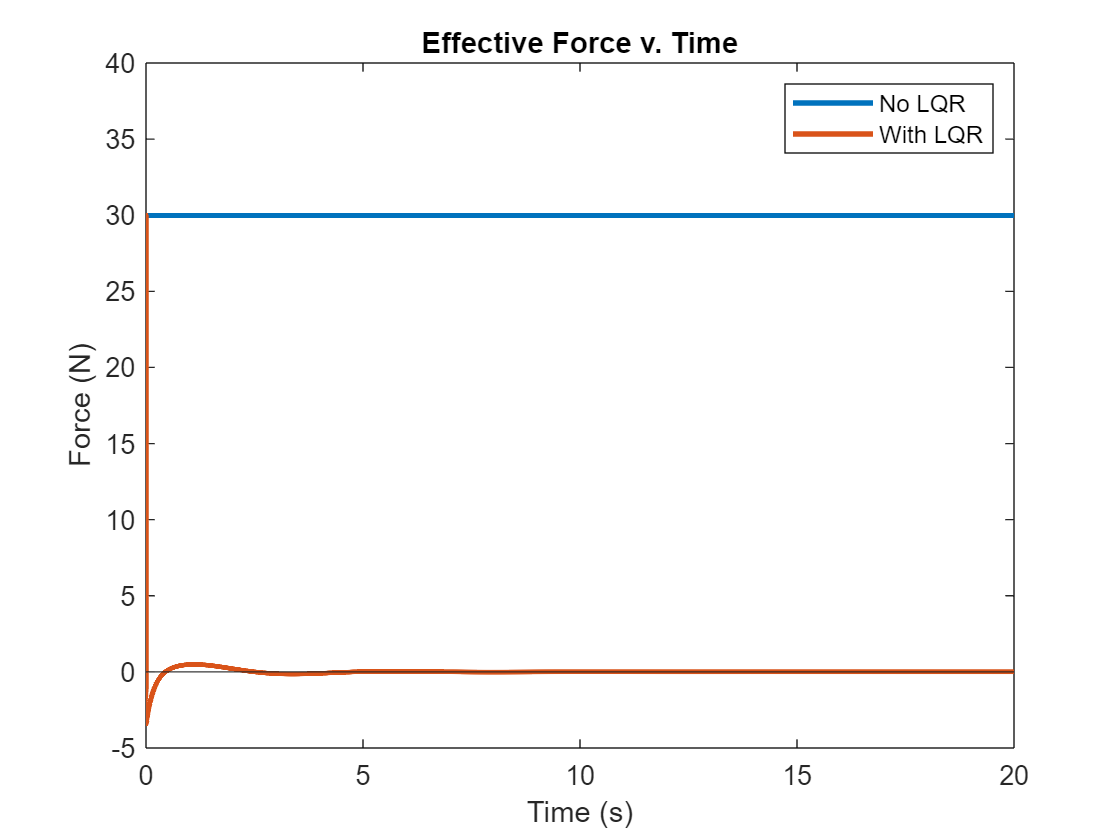

sr.plotF;
hold on
sr2.plotF
hold off
legend()
%xlim([0,0.25])
ylim([-5 40])

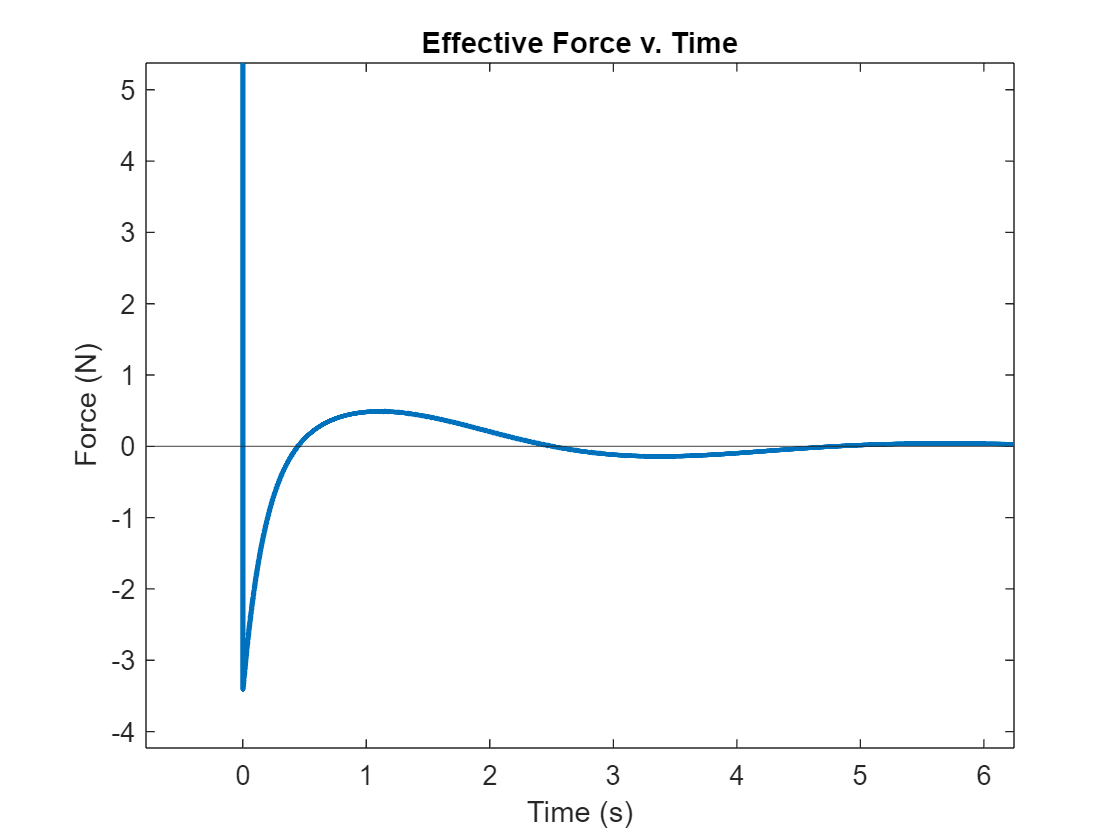

sr2.plotF

xlim([-0.78 6.24])
ylim([-4.23 5.38])

#### Varying Force

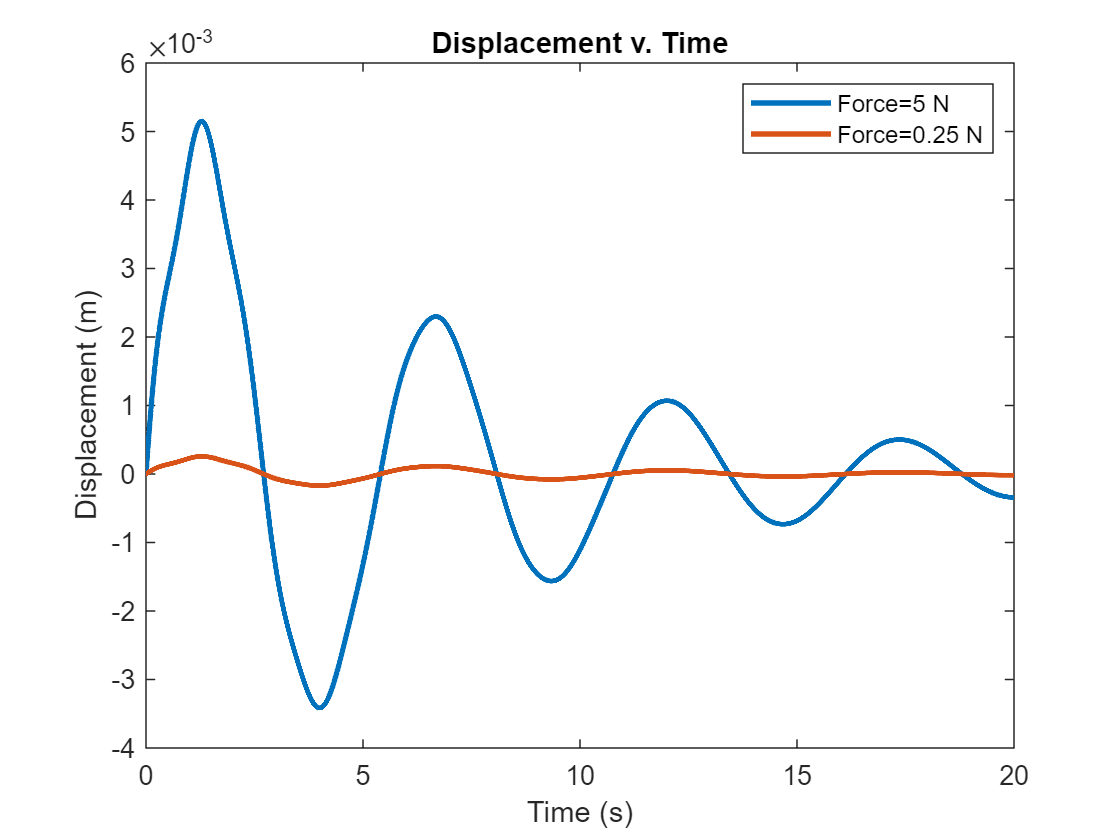

time_t = [0:0.001:20];
IP = InvertedPendulum();
%V0 = [0;0; 0.175;0]; % initial bar tilt 10 degrees
V0 = [0;0; 0;0];
Force =5;
Q = [1 0 0 0;
     0 0 0 0;
     0 0 1 0;
     0 0 0 0];
R=1;
N = [1;0;0;0];

sr = IP.euler_method(V0, 5, time=time_t, lqr=true, ...
    Q=Q,N=N,R=R, description='Force=5 N');

sr.plotX;

sr2 = IP.euler_method(V0, 0.25, time=time_t, lqr=true, ...
    Q=Q,N=N,R=R, description='Force=0.25 N');
hold on
sr2.plotX
hold off
legend()

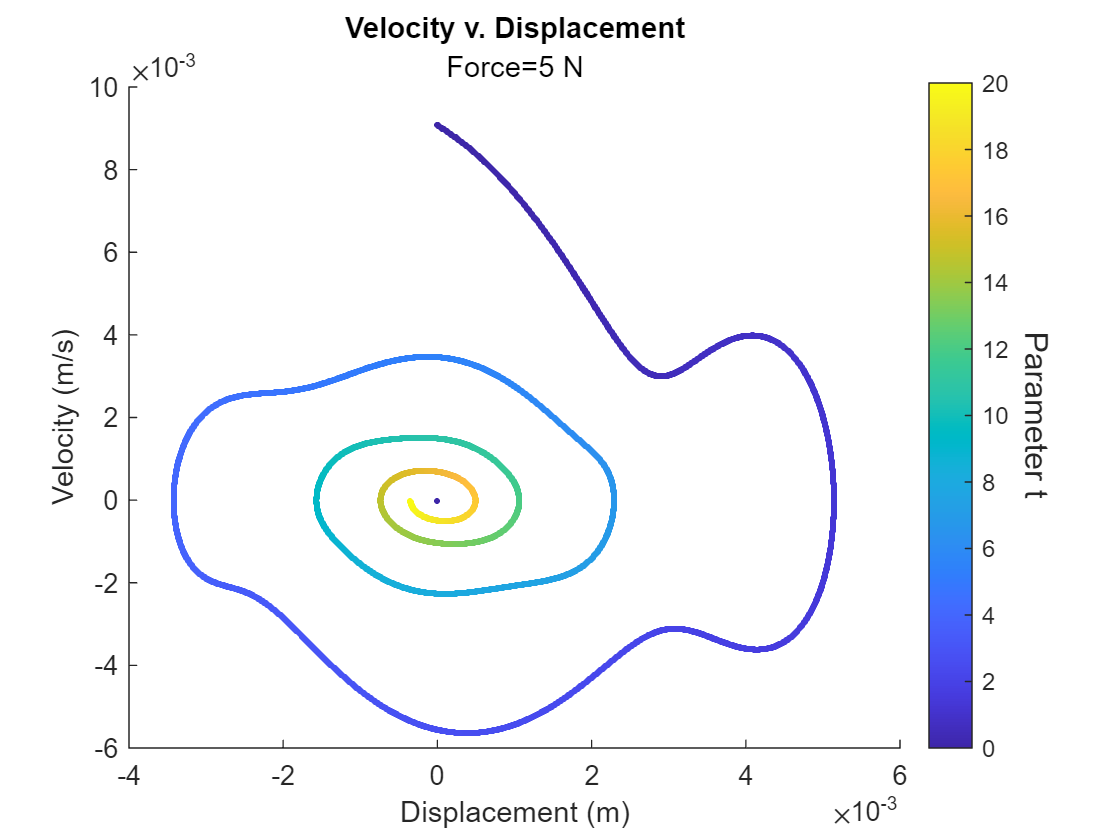

sr.plotXdX()

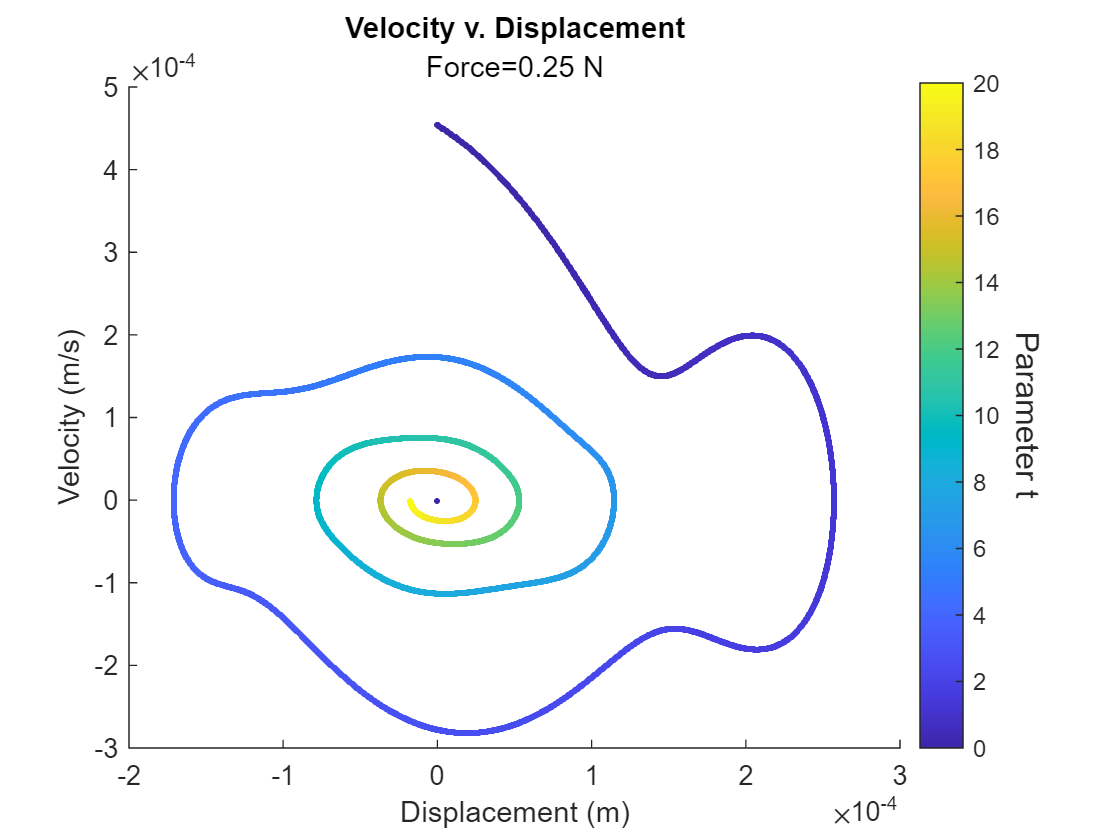

sr2.plotXdX()

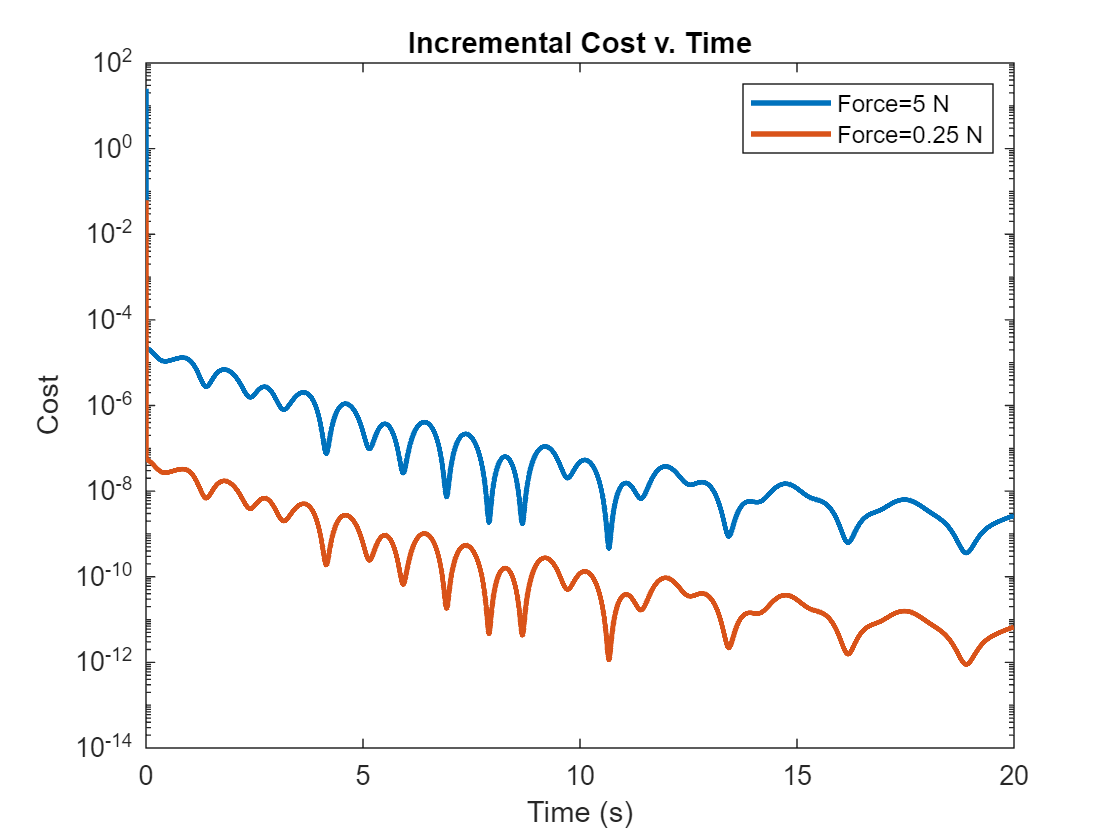

sr.plotdC;
hold on
sr2.plotdC
hold off
legend()

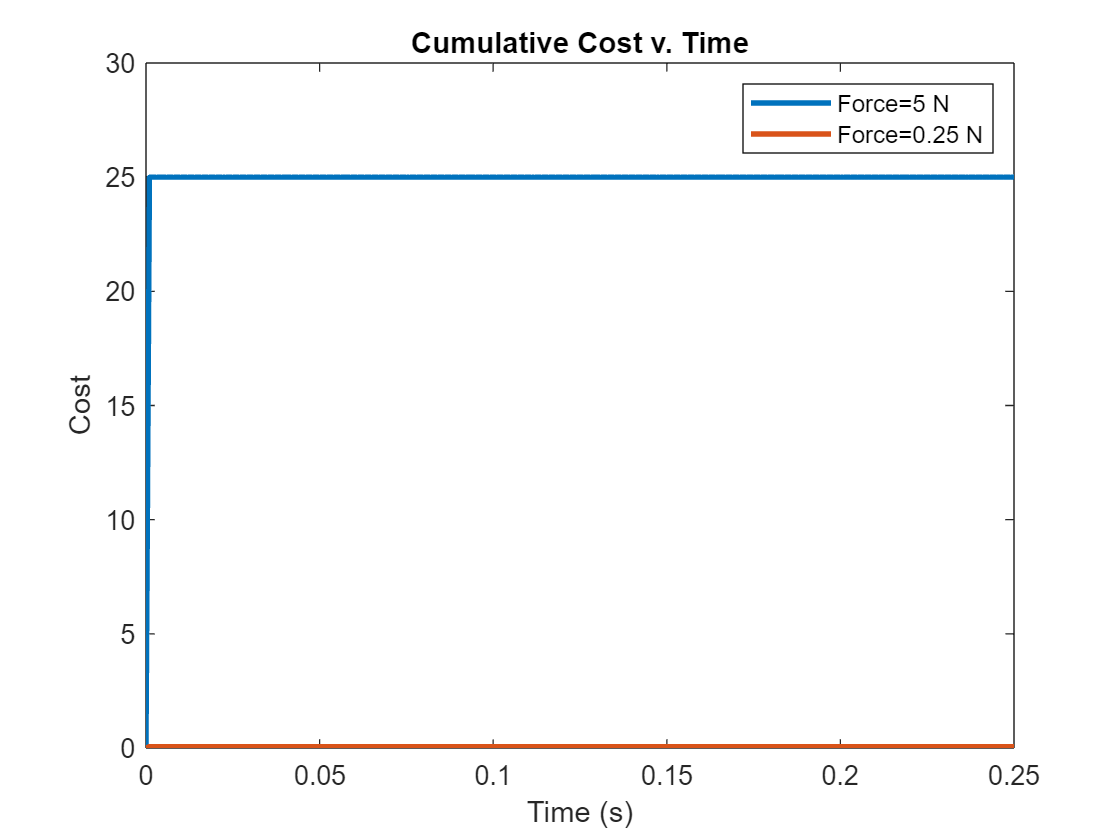


sr.plotdC(cumulative=true);
hold on
sr2.plotdC(cumulative=true)
hold off
legend()
xlim([0,0.25])

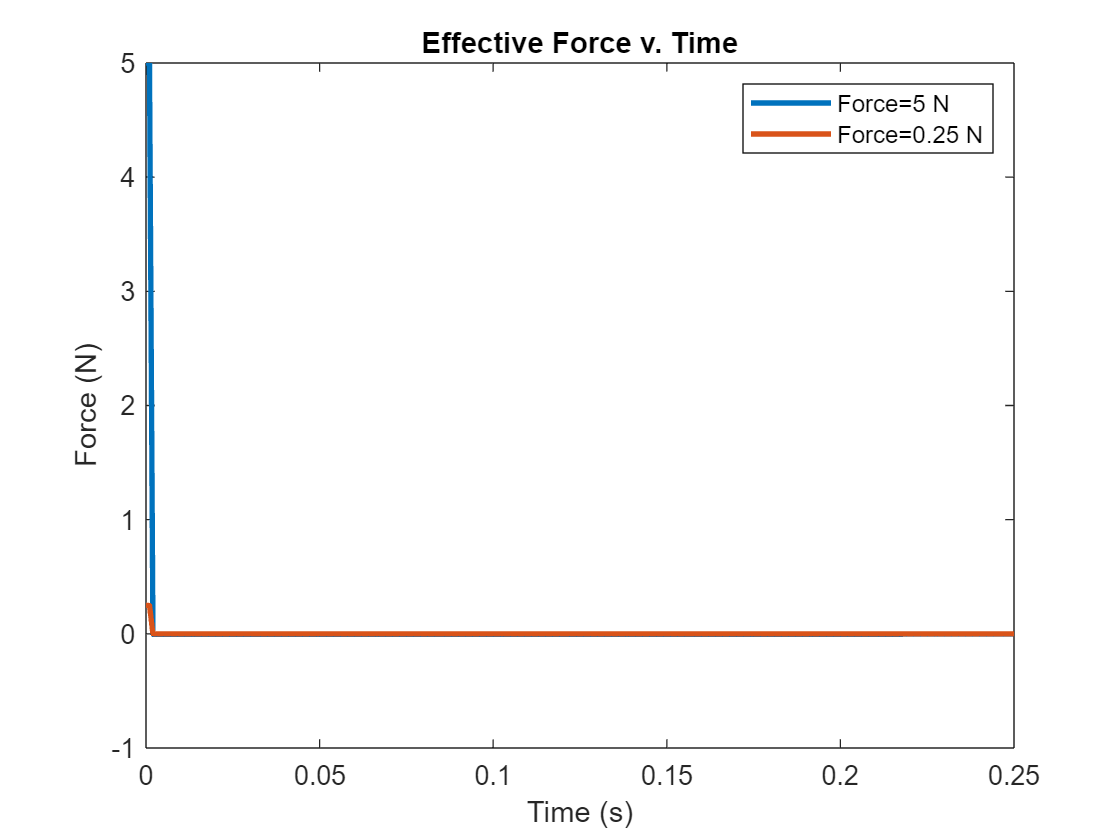

sr.plotF;
hold on
sr2.plotF
hold off
legend()
xlim([0,0.25])

IP =   InvertedPendulum with properties:

    M: 0.5000
    m: 0.2000
    b: 0.1000
    l: 0.3000
    I: 0.0060
    g: 9.8000
    A: [4×4 double]
    B: [4×1 double]


IP_highfriction =   InvertedPendulum with properties:

    M: 8.5000
    m: 0.2000
    b: 0.5000
    l: 0.3000
    I: 0.0060
    g: 9.8000
    A: [4×4 double]
    B: [4×1 double]


sr =   SimResult with properties:

             Vt: [4×301 double]
             dC: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ]
         time_t: [0 0.0100 0.0200 0.0300 0.0400 0.0500 0.0600 0.0700 0.0800 0.0900 0.1000 0.1100 0.1200 0.1300 0.1400 0.1500 0.1600 0.1700 0.1800 0.1900 0.2000 0.2100 0.2200 0.2300 0.2400 0.2500 0.2600 0.2700 0.2800 0.2900 0.3000 0.3100 0.3200 0.3300 … ]
          force: 5
             ut: [5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 5 … ]
    description: 'Simulation'


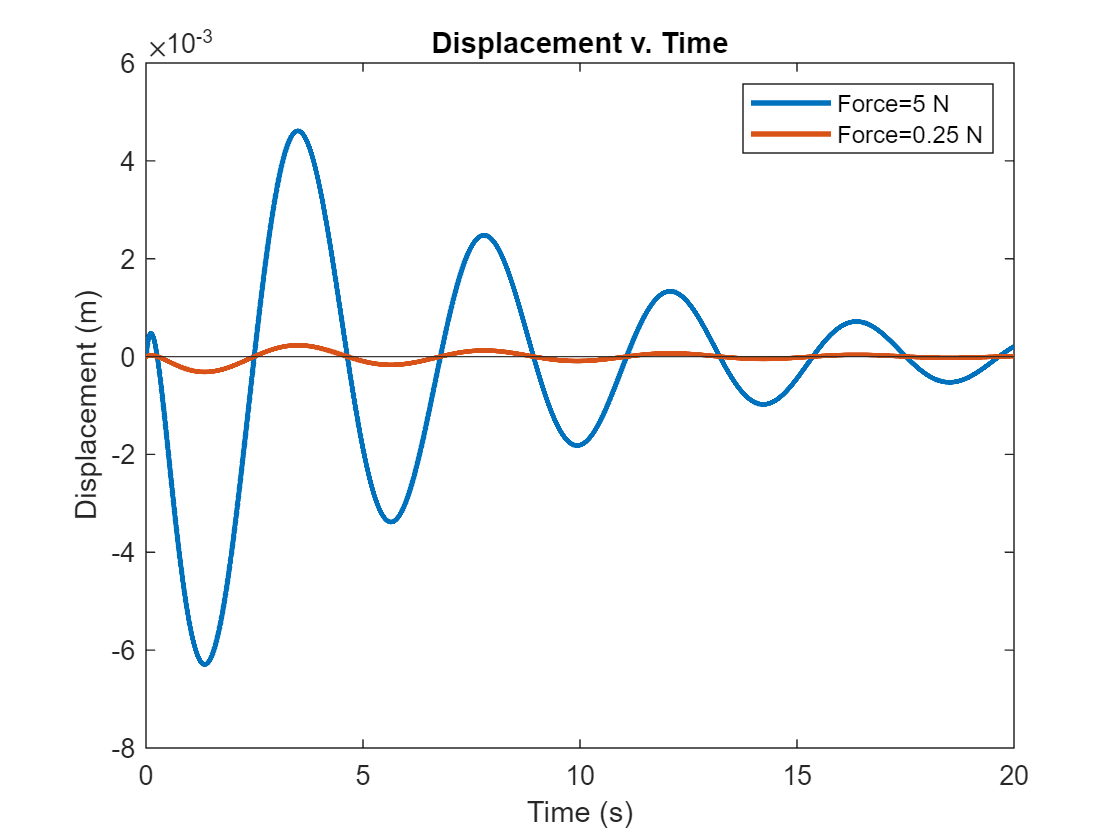


run('HowToExperiment.mlx')